clc;
clear;
close all;

%communities description
labels = ["Environmental Attitude" "Behavioral Attitude" "Subjective norm" "Perceived control"];
iterations = 40;

%Case 1 - symetric population
%[size, [mean, std] ae, [mean, std] ab, [mean, std] sn, [mean, std] pc]
c11 = [5e2 1 0 1 0 0.1 0.1 0.5 0.2];
c12 = [5e2 -1 0 -1 0 0.1 0.1 0.5 0.2];
c13 = [4e3 0 0.2 0 0.2 0.3 0.05 0 0.2];
c14 = [1e3 0.8 0.2 0.7 0.3 0.8 0.05 0 0.2];
c15 = [1e3 -0.8 0.2 -0.7 0.3 0.8 0.05 0 0.2];
%[[mean, std] amount, [mean, std] power, std distribution] community;
%[mean, std] amount, [mean, std] power, std distribution] population]
l11 = [0 0 0 0 0; 40 10 0.5 0.2 50];
l12 = [0 0 0 0 0; 40 10 0.5 0.2 50];
l13 = [0 0 0 0 0; 40 10 0.5 0.2 50];
l14 = [100 10 0.5 0.2 50; 30 10 0.2 0.2 -1];
l15 = [100 10 0.5 0.2 50; 30 10 0.2 0.2 -1];

%parameters
comm1 = [c11; c12; c13; c14; c15];
links1 = [l11; l12; l13; l14;l15];

%Case 2 - biased population (disposables)
%[size, [mean, std] ae, [mean, std] ab, [mean, std] sn, [mean, std] pc]
c21 = [4e2 1 0 1 0 0.5 0.05 0.4 0.2];
c22 = [6e2 -1 0 -1 0 0.5 0.05 0.4 0.2];
c23 = [3e3 -0.6 0.2 -0.4 0.2 0.5 0.05 0 0.2];
c24 = [1e3 0.8 0.2 0.7 0.3 0.8 0.05 0.5 0.2];
c25 = [2e3 -0.8 0.2 -0.7 0.3 0.9 0.05 0.5 0.2];
%[[mean, std] amount, [mean, std] power, std distribution] community;
%[mean, std] amount, [mean, std] power, std distribution] population]
l21 = [0 0 0 0 0; 100 10 0.5 0.2 1000];
l22 = [0 0 0 0 0; 100 10 0.5 0.2 1000];
l23 = [0 0 0 0 0; 100 10 0.5 0.2 1000];
l24 = [100 10 0.5 0.2 -1; 40 10 0.2 0.2 -1];
l25 = [100 10 0.5 0.2 -1; 40 10 0.2 0.2 -1];

%parameters
comm2 = [c21; c22; c23; c24; c25];
links2 = [l21; l22; l23; l24;l25];

%Case 3 - communities-based population
%[size, [mean, std] ae, [mean, std] ab, [mean, std] sn, [mean, std] pc]
c31 = [4e2 1 0 1 0 0.5 0.05 0.4 0.2];
c32 = [6e2 -1 0 -1 0 0.5 0.05 0.4 0.2];
c33 = [3e3 -0.6 0.2 -0.4 0.2 0.5 0.05 0 0.2];
c34 = [1e3 0.8 0.2 0.7 0.3 0.8 0.05 0.5 0.2];
c35 = [2e3 -0.8 0.2 -0.7 0.3 0.9 0.05 0.5 0.2];
%[[mean, std] amount, [mean, std] power, std distribution] community;
%[mean, std] amount, [mean, std] power, std distribution] population]
l31 = [120 10 0.9 0.2 -1; 5 2 0 0.2 -1];
l32 = [120 10 0.9 0.2 -1; 10 2 0 0.2 -1];
l33 = [140 10 0.9 0.2 -1; 10 2 0 0.2 -1];
l34 = [150 10 0.9 0.2 -1; 5 2 0 0.2 -1];
l35 = [150 10 0.9 0.2 -1; 5 2 0 0.2 -1];
%%

%parameters
comm3 = [c31; c32; c33; c34; c35];
links3 = [l31; l32; l33; l34; l35];

%Case 4 - connected population
%[size, [mean, std] ae, [mean, std] ab, [mean, std] sn, [mean, std] pc]
%[size, [mean, std] ae, [mean, std] ab, [mean, std] sn, [mean, std] pc]
c41 = [4e2 1 0 1 0 0.5 0.05 0.4 0.2];
c42 = [6e2 -1 0 -1 0 0.5 0.05 0.4 0.2];
c43 = [3e3 -0.6 0.2 -0.4 0.2 0.5 0.05 0 0.2];
c44 = [1e3 0.8 0.2 0.7 0.3 0.8 0.05 0.5 0.2];
c45 = [2e3 -0.8 0.2 -0.7 0.3 0.9 0.05 0.5 0.2];
%[[mean, std] amount, [mean, std] power, std distribution] community;
%[mean, std] amount, [mean, std] power, std distribution] population]
l41 = [0 0 0 0 0; 300 10 0.8 0.2 -1];
l42 = [0 0 0 0 0; 300 10 0.8 0.2 -1];
l43 = [0 0 0 0 0; 300 10 0.8 0.2 -1];
l44 = [100 10 0.2 0.2 -1; 150 10 0.8 0.2 -1];
l45 = [100 10 0.8 0.2 -1; 150 10 0.2 0.2 -1];

%parameters
comm4 = [c41; c42; c43; c44; c45];
links4 = [l41; l42; l43; l44;l45];

%CASE 1

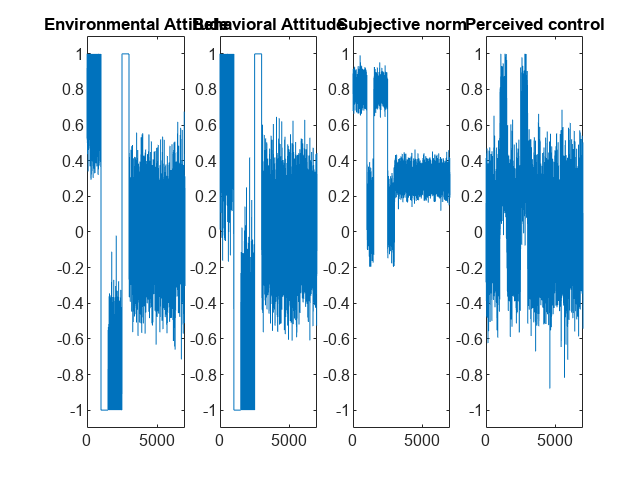

%population construction
[population1, network1, vec1] = PopDesign(comm1, links1, 0);
%Community statistics
CommDisplay(population1, labels)

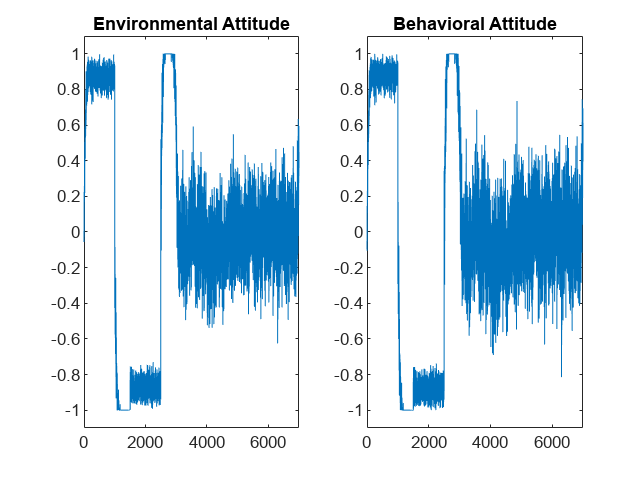

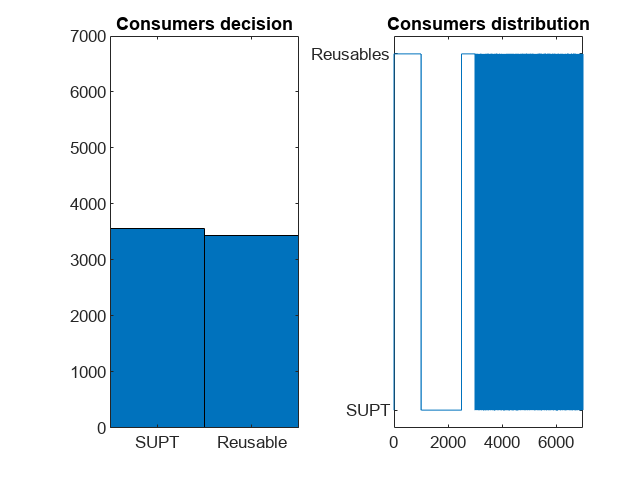

%Evolutionary game
[Decision1, pop_updated1] = EvoGame(population1, network1, labels, iterations);

Decision10 = Decision1(1,:);
Decision11 = Decision1(end,:);

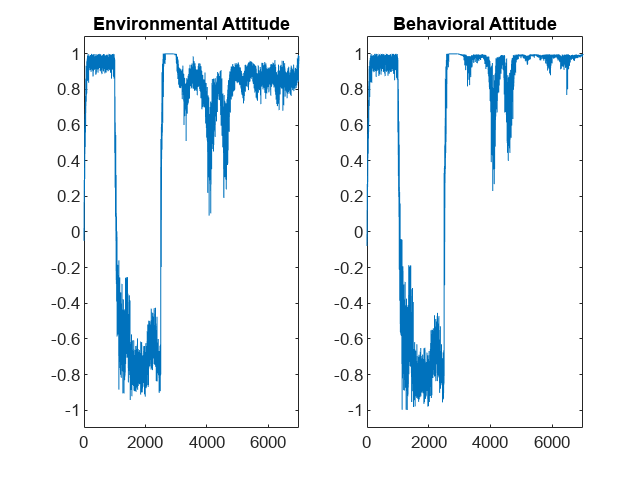

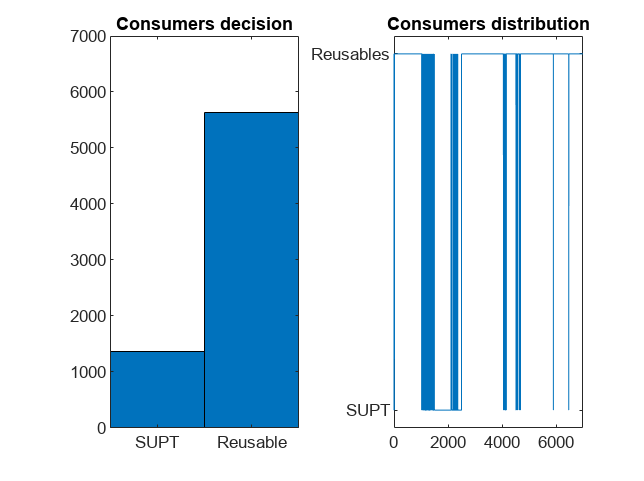

%Interventions
intervention12 = [100 0 0 0];
intervention13 = [0 100 0 0];
population12 = Intervention(pop_updated1, comm1, vec1, intervention12, 0);
population13 = Intervention(pop_updated1, comm1, vec1, intervention13, 0);
[Decision121, pop_updated12] = EvoGame(population12, network1, labels, iterations);

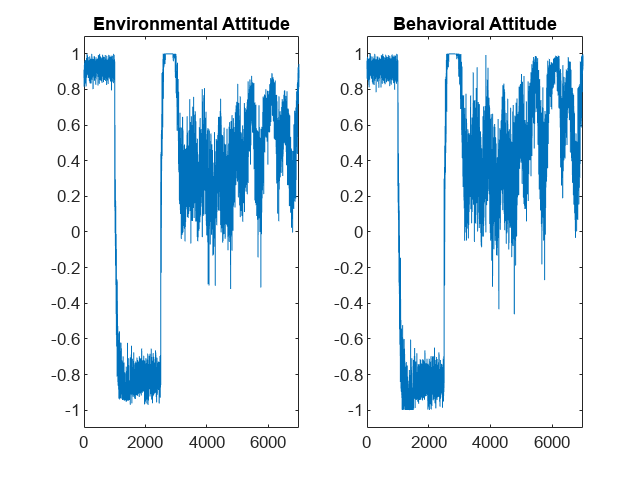

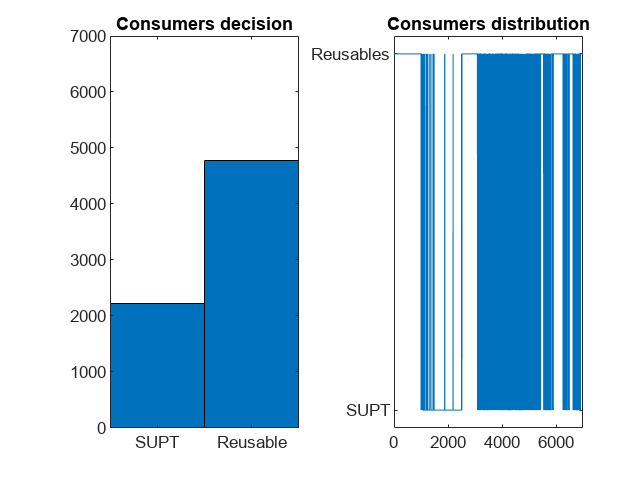

[Decision131, pop_updated13] = EvoGame(population13, network1, labels, iterations);

Decision12 = Decision121(end,:);
Decision13 = Decision131(end,:);

%CASE 2

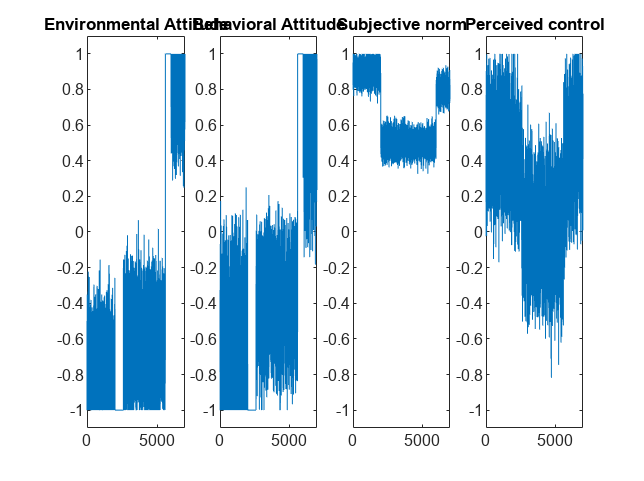

%population construction
[population2, network2, vec2] = PopDesign(comm2, links2, 0);
%Community statistics
CommDisplay(population2, labels)

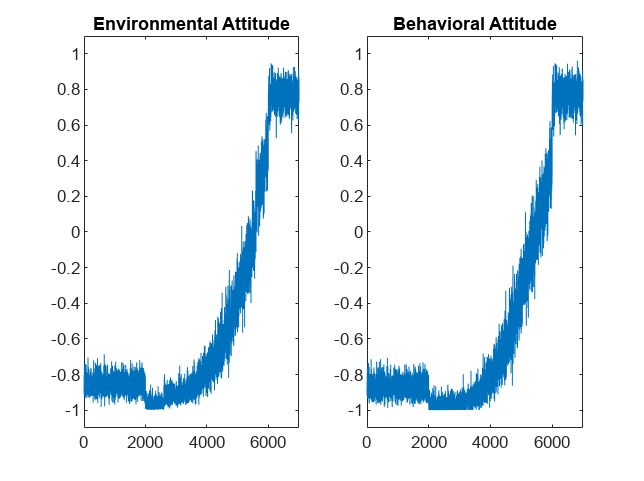

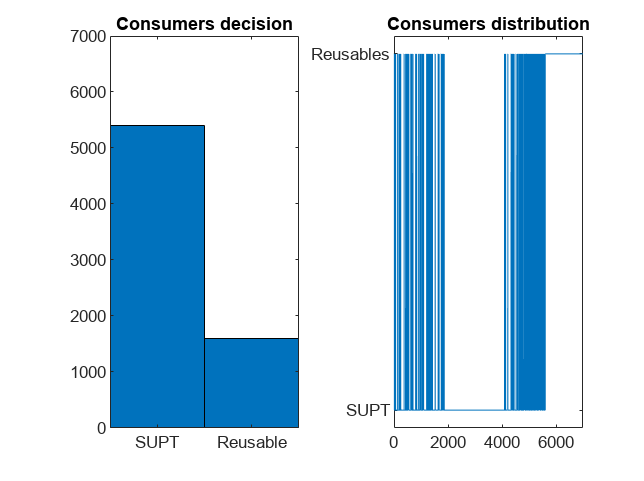

%Evolutionary game
[Decision2, pop_updated2] = EvoGame(population2, network2, labels, iterations);

Decision20 = Decision2(1,:);
Decision21 = Decision2(end,:);

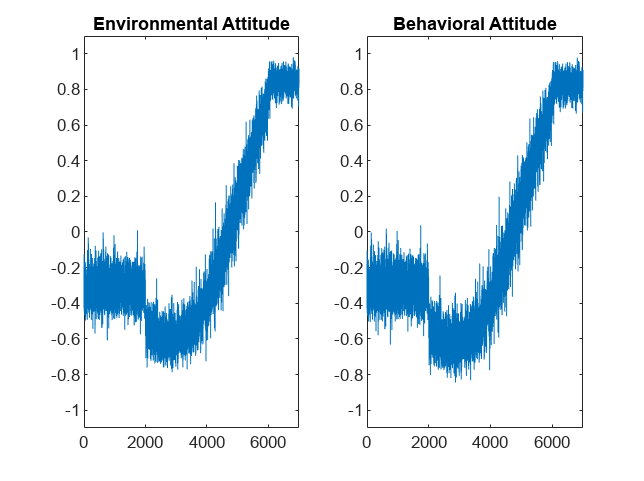

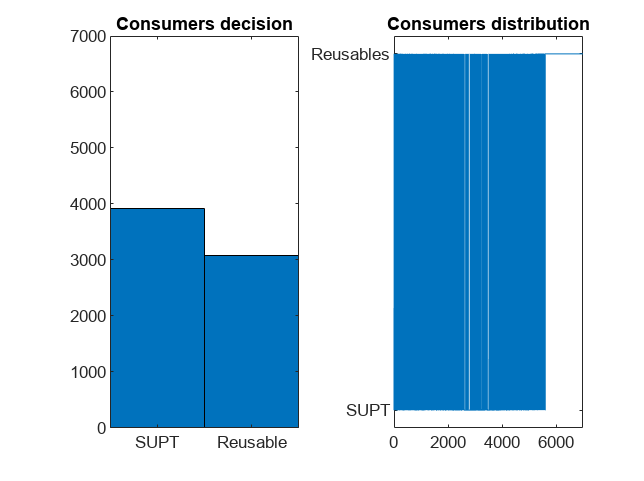

%Interventions
intervention22 = [100 0 0 0];
intervention23 = [0 100 0 0];
population22 = Intervention(pop_updated2, comm2, vec2, intervention22, 0);
population23 = Intervention(pop_updated2, comm2, vec2, intervention23, 0);
[Decision221, pop_updated22] = EvoGame(population22, network2, labels, iterations);

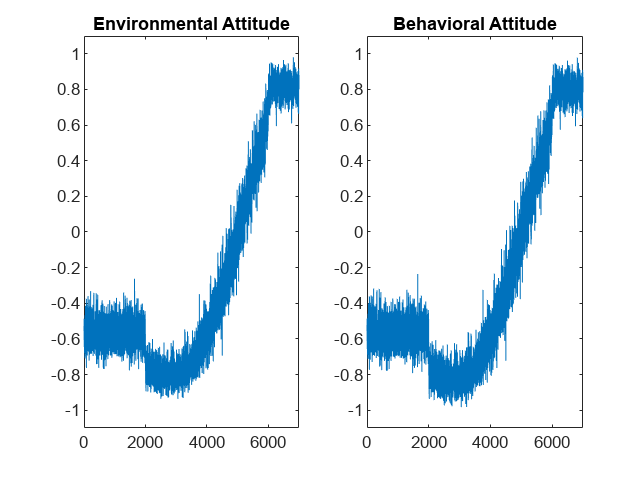

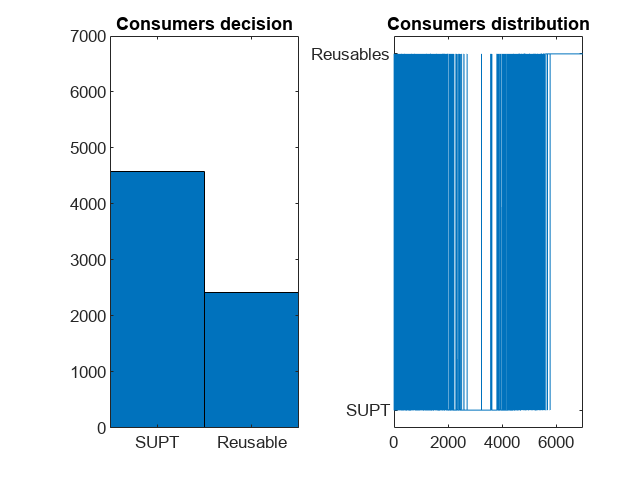

[Decision231, pop_updated23] = EvoGame(population23, network2, labels, iterations);

Decision22 = Decision221(end,:);
Decision23 = Decision231(end,:);

%CASE 3

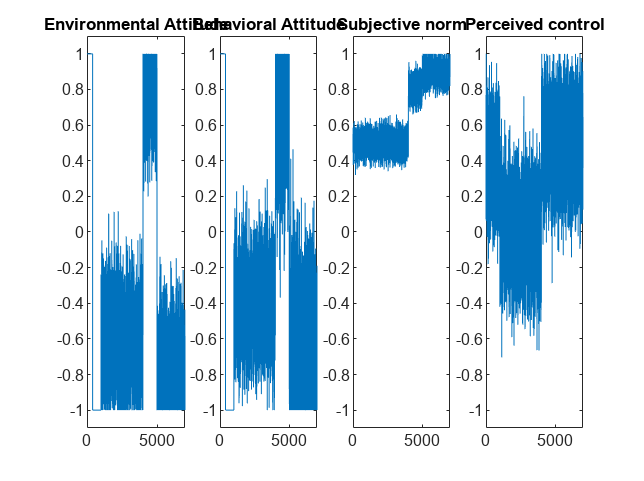

%population construction
[population3, network3, vec3] = PopDesign(comm3, links3, 0);
%Community statistics
CommDisplay(population3, labels)

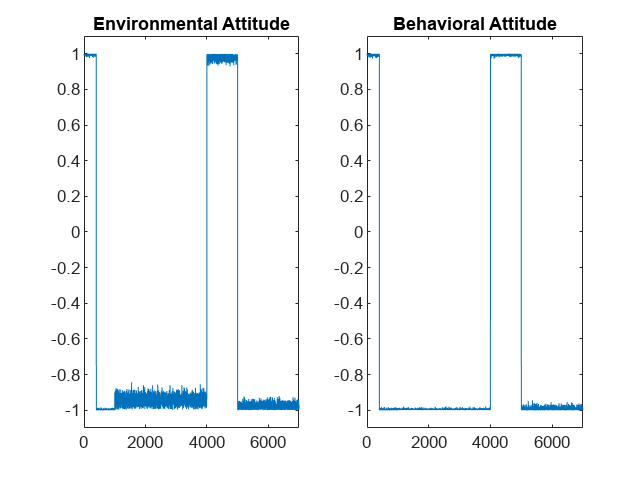

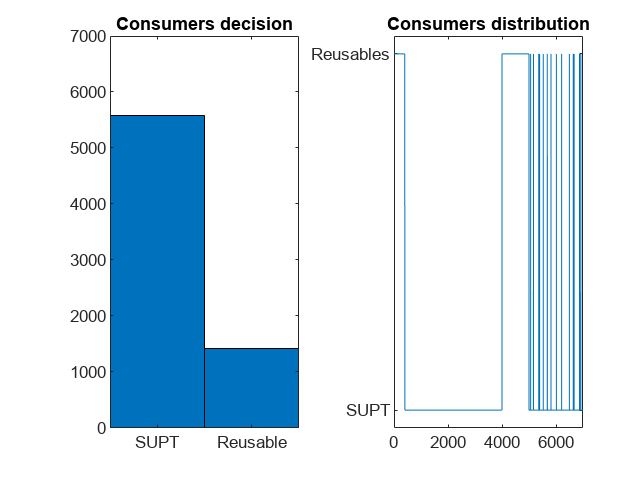

%Evolutionary game
[Decision3, pop_updated3] = EvoGame(population3, network3, labels, iterations);

Decision30 = Decision3(1,:);
Decision31 = Decision3(end,:);

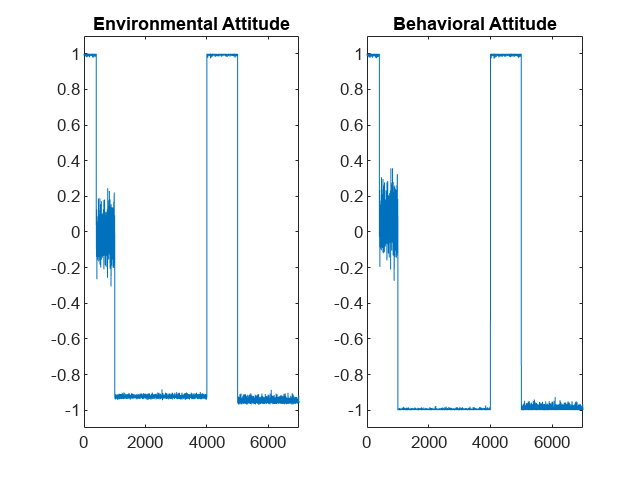

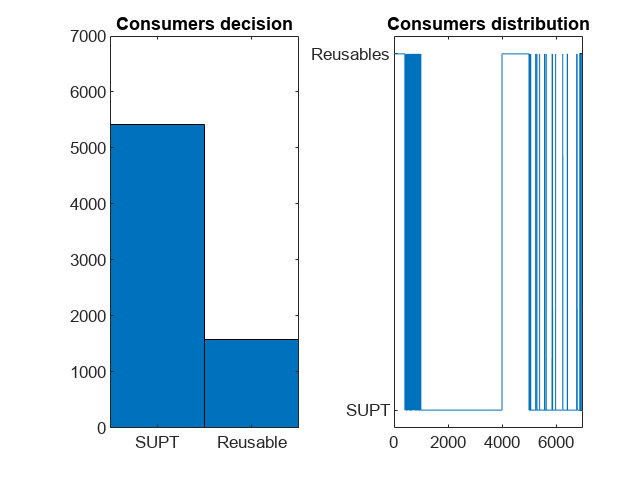

%Interventions
intervention32 = [100 0 0 0];
intervention33 = [0 100 0 0];
population32 = Intervention(pop_updated3, comm3, vec3, intervention32, 0);
population33 = Intervention(pop_updated3, comm3, vec3, intervention33, 0);
[Decision321, pop_updated32] = EvoGame(population32, network3, labels, iterations);

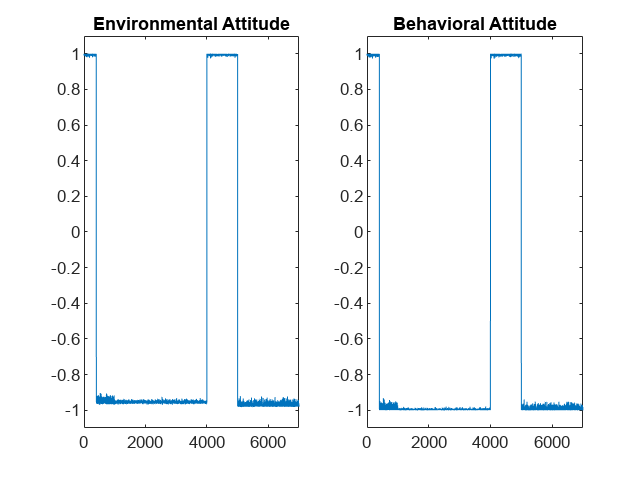

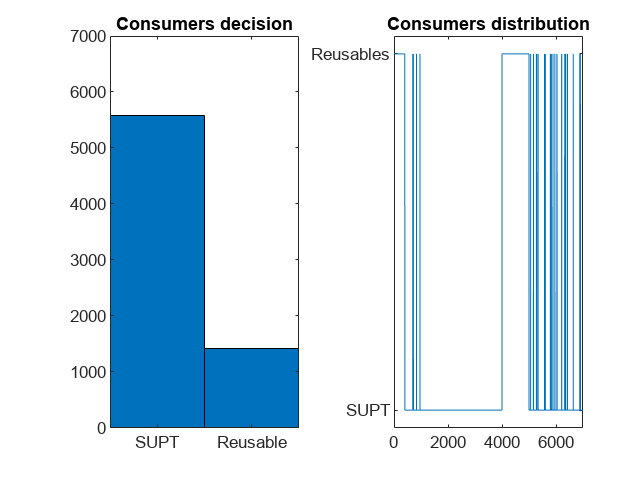

[Decision331, pop_updated33] = EvoGame(population33, network3, labels, iterations);

Decision32 = Decision321(end,:);
Decision33 = Decision331(end,:);

%CASE 4

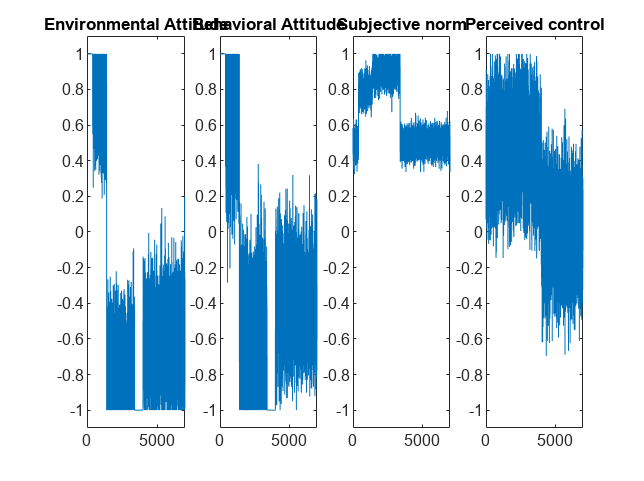

%population construction
[population4, network4, vec4] = PopDesign(comm4, links4, 0);
%Community statistics
CommDisplay(population4, labels)

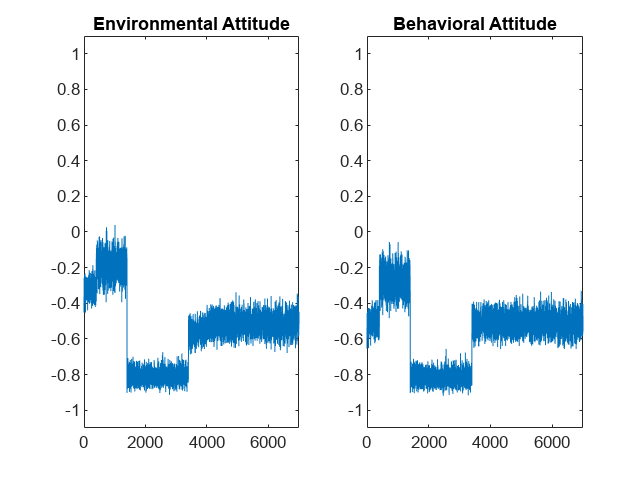

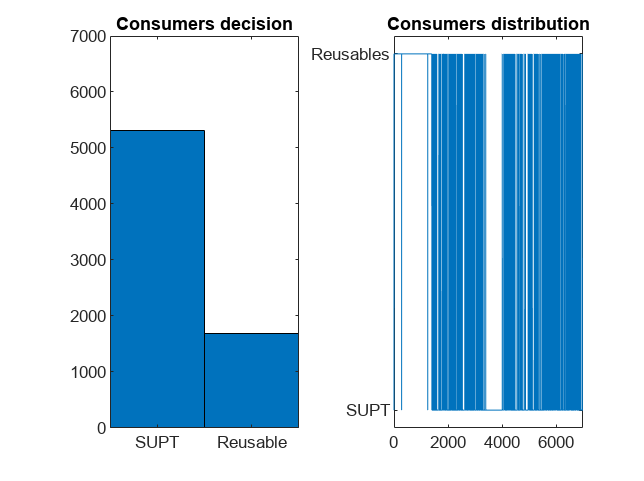

%Evolutionary game
[Decision4, pop_updated4] = EvoGame(population4, network4, labels, iterations);

Decision40 = Decision4(1,:);
Decision41 = Decision4(end,:);

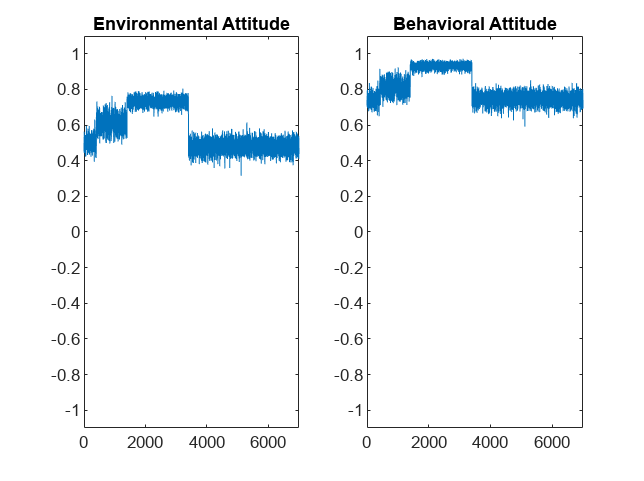

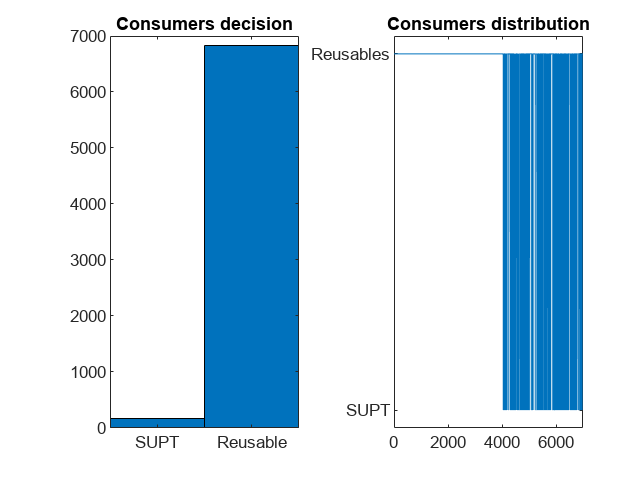

%Interventions
intervention42 = [100 0 0 0];
intervention43 = [0 100 0 0];
population42 = Intervention(pop_updated4, comm4, vec4, intervention42, 0);
population43 = Intervention(pop_updated4, comm4, vec4, intervention43, 0);
[Decision421, pop_updated42] = EvoGame(population42, network4, labels, iterations);

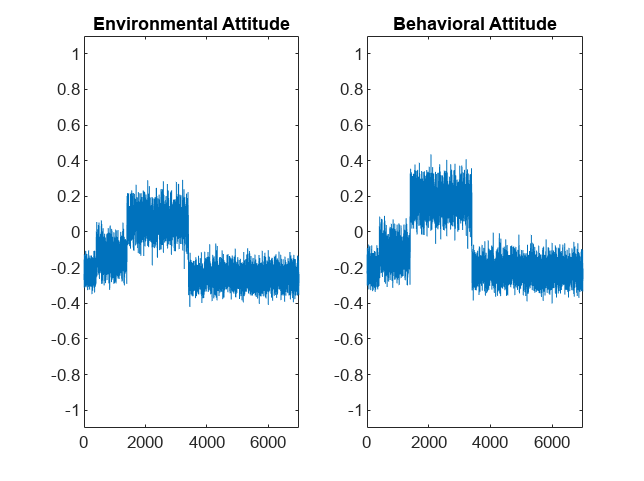

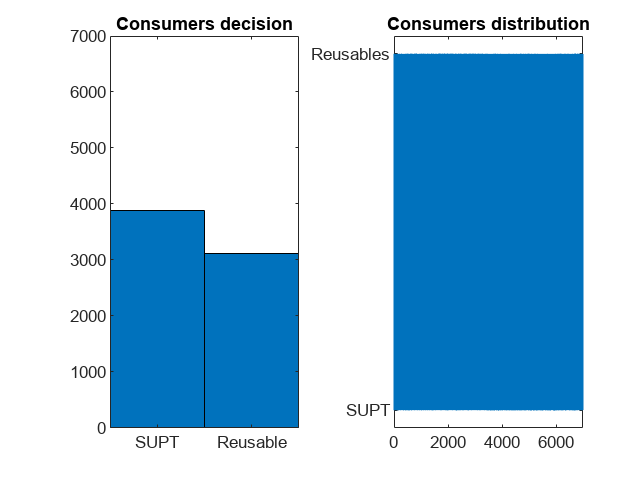

[Decision431, pop_updated43] = EvoGame(population43, network4, labels, iterations);

Decision42 = Decision421(end,:);
Decision43 = Decision431(end,:);

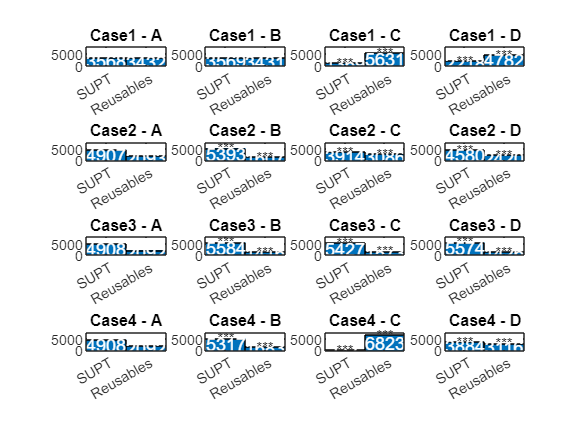

%display cases
figure;

%CASE 1
subplot(4, 4, 1)
DecisionDisplay(Decision10, 'Case1 - A', [], false)
subplot(4, 4, 2)
DecisionDisplay(Decision11, 'Case1 - B', Decision10, true)
subplot(4, 4, 3)
DecisionDisplay(Decision12, 'Case1 - C', Decision10, true)
subplot(4, 4, 4)
DecisionDisplay(Decision13, 'Case1 - D', Decision10, true)

%CASE 2
subplot(4, 4, 5)
DecisionDisplay(Decision20, 'Case2 - A', [], false)
subplot(4, 4, 6)
DecisionDisplay(Decision21, 'Case2 - B', Decision20, true)
subplot(4, 4, 7)
DecisionDisplay(Decision22, 'Case2 - C', Decision20, true)
subplot(4, 4, 8)
DecisionDisplay(Decision23, 'Case2 - D', Decision20, true)

%CASE 3
subplot(4, 4, 9)
DecisionDisplay(Decision30, 'Case3 - A', [], false)
subplot(4, 4, 10)
DecisionDisplay(Decision31, 'Case3 - B', Decision30, true)
subplot(4, 4, 11)
DecisionDisplay(Decision32, 'Case3 - C', Decision22, true)
subplot(4, 4, 12)
DecisionDisplay(Decision33, 'Case3 - D', Decision23, true)

%CASE 4
subplot(4, 4, 13)
DecisionDisplay(Decision40, 'Case4 - A', [], false)
subplot(4, 4, 14)
DecisionDisplay(Decision41, 'Case4 - B', Decision40, true)
subplot(4, 4, 15)
DecisionDisplay(Decision42, 'Case4 - C', Decision40, true)
subplot(4, 4, 16)
DecisionDisplay(Decision43, 'Case4 - D', Decision23, true)

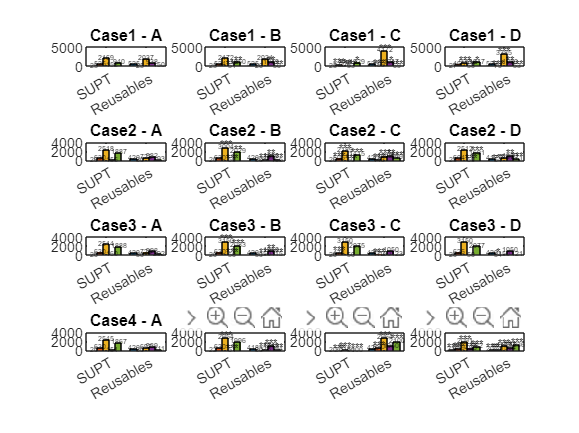

%display cases by community
figure;
%CASE 1
subplot(4, 4, 1)
DecisionDisplayComm(Decision10, comm1, vec1, 'Case1 - A', [], false);
subplot(4, 4, 2)
DecisionDisplayComm(Decision11, comm1, vec1, 'Case1 - B', Decision10, true)
subplot(4, 4, 3)
DecisionDisplayComm(Decision12, comm1, vec1, 'Case1 - C', Decision10, true)
subplot(4, 4, 4)
DecisionDisplayComm(Decision13, comm1, vec1, 'Case1 - D', Decision10, true)

%CASE 2
subplot(4, 4, 5)
DecisionDisplayComm(Decision20, comm2, vec2, 'Case2 - A', [], false)
subplot(4, 4, 6)
DecisionDisplayComm(Decision21, comm2, vec2, 'Case2 - B', Decision20, true)
subplot(4, 4, 7)
DecisionDisplayComm(Decision22, comm2, vec2, 'Case2 - C', Decision20, true)
subplot(4, 4, 8)
DecisionDisplayComm(Decision23, comm2, vec2, 'Case2 - D', Decision20, true)

%CASE 3
subplot(4, 4, 9)
DecisionDisplayComm(Decision30, comm3, vec3, 'Case3 - A', [], false)
subplot(4, 4, 10)
DecisionDisplayComm(Decision31, comm3, vec3, 'Case3 - B', Decision30, true)
subplot(4, 4, 11)
DecisionDisplayComm(Decision32, comm3, vec3, 'Case3 - C', Decision31, true)
subplot(4, 4, 12)
DecisionDisplayComm(Decision33, comm3, vec3, 'Case3 - D', Decision31, true)

%CASE 4
subplot(4, 4, 13)
DecisionDisplayComm(Decision40, comm4, vec4, 'Case4 - A', [], false)
subplot(4, 4, 14)
DecisionDisplayComm(Decision41, comm4, vec4, 'Case4 - B', Decision31, true)
subplot(4, 4, 15)
DecisionDisplayComm(Decision42, comm4, vec4, 'Case4 - C', Decision41, true)
subplot(4, 4, 16)
DecisionDisplayComm(Decision43, comm4, vec4, 'Case4 - D', Decision41, true)